# Aula 8 - Laboratório de Controle - 2021/1

## Projeto do controlador PID via LR

## Nome: Arthur Lorencini Bergamaschi

[Video sobre este live script](https://youtu.be/QTGdJ07Edbw)

turma=1 ;
I=2 ;
Tempo=3;

M=[5 9 3 4 1 2 12 7 11 10 8 6
     2 4 5 11 10 1 9 8 7 3 6 12
     9 1 12 8 5 11 6 3 2 4 10 7
     7 6 9 2 11 5 8 4 3 10 12 1
    12 9 3 11 7 8 5 2 10 1 6 4]';

wn=M(I,turma);

arquivo='motor_cc_R2019.slx';  
load dados.mat
i=wn*50;
ind=(i-20):(i+35);
y1=y1(ind);
u1=u1(ind);
t1=t1(ind);
Ref=mean(y1(end-10:end));
u0=mean(u1(1:10));


## Atividade 0 - Obtenção do modelo

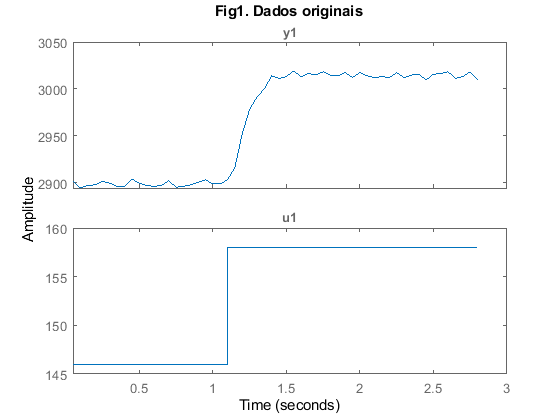

dat=iddata(y1,u1,Ts);
dat_1=iddata(y1-y1(1),u1-u1(1),Ts);
figure
plot(dat);title('Fig1. Dados originais');

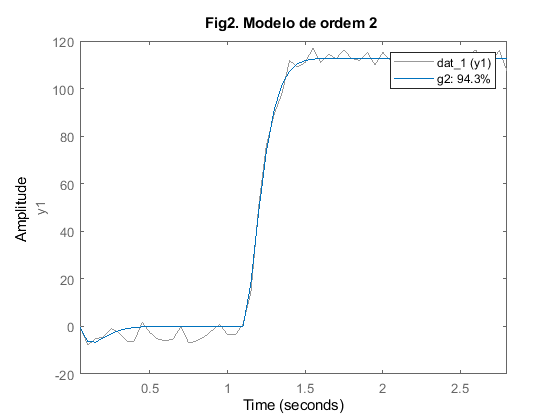

g2=tfest(dat_1,2,0);
g2=tf(g2.Numerator,g2.Denominator);
K=freqresp(g2,0);
figure
compare(dat_1,g2);title('Fig2. Modelo de ordem 2 ');

s=stepinfo(g2);
ts_ma=s.SettlingTime

ts_ma = 0.3451

N=100;
Ts=0.01;

## Atividade 1 - Projeto do controlador PI via LR e simulação com g2

1.1 Use o LR para projetar o controlador PI para g2 de modo a atender $UP<5\%$e o menor tempo de estabelecimento possível, necessariamente menor que o de malha aberta (ts_ma). Gere 5 controladores PI C1...C5 para 5 localizações do zero Ki/Kp, como explicado no video, ajustando Kp para o menor tempo de estabelecimento.

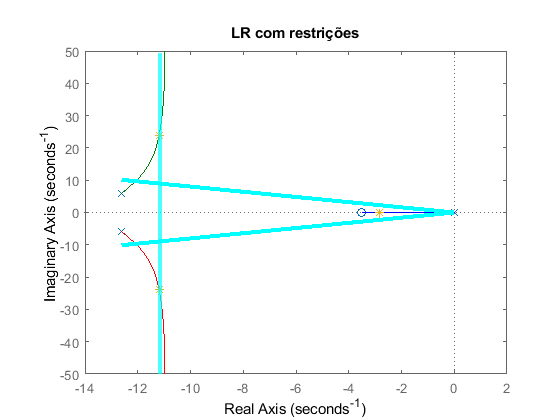

figure
desenhalr(C1,g2,ts_ma);

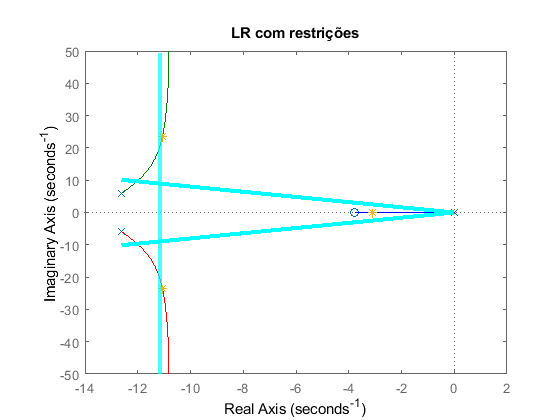

m1=feedback(C1*g2,1);
s=stepinfo(m1);
upc=[s.Overshoot];
tsc=[s.SettlingTime];

figure
desenhalr(C2,g2,ts_ma);

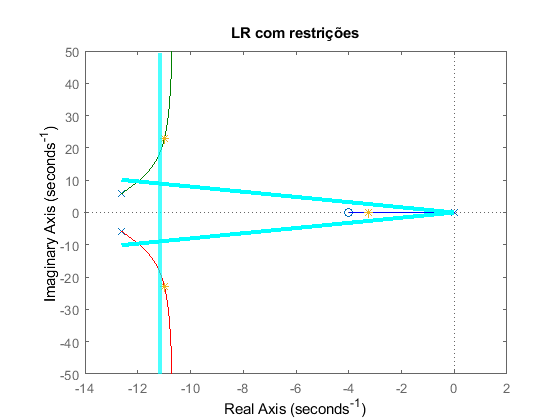

m2=feedback(C2*g2,1);
s=stepinfo(m2);
upc=[upc s.Overshoot];
tsc=[tsc s.SettlingTime];

figure
desenhalr(C3,g2,ts_ma);

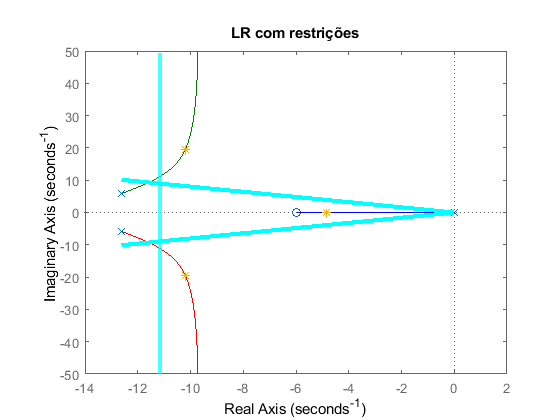

m3=feedback(C3*g2,1);
s=stepinfo(m3);
upc=[upc s.Overshoot];
tsc=[tsc s.SettlingTime];

figure
desenhalr(C4,g2,ts_ma);

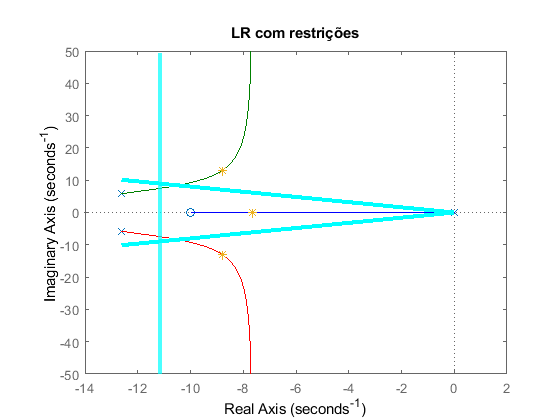

m4=feedback(C4*g2,1);
s=stepinfo(m4);
upc=[upc s.Overshoot];
tsc=[tsc s.SettlingTime];


figure;
desenhalr(C5,g2,ts_ma);

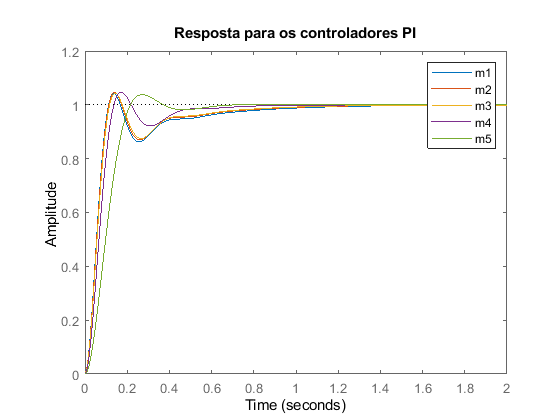

m5=feedback(C5*g2,1);
s=stepinfo(m5);
upc=[upc s.Overshoot];
tsc=[tsc s.SettlingTime];

figure
step(m1,m2,m3,m4,m5);legend('m1','m2','m3','m4','m5');
title('Resposta para os controladores PI');

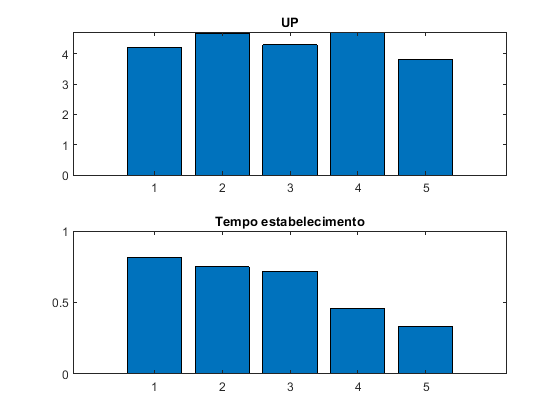


figure
subplot(2,1,1);bar(upc);title('UP')
subplot(2,1,2);bar(tsc);title('Tempo estabelecimento');

Vale ressaltar que não foi encontrado quase nenhum valor para os zeros que satisfazem a relação do tempo de estabelecimento para o PI para o modelo de G2. Apesar de variar os valores de kp e dos zeros.

## Atividade 2 - Teste do controlador PI no motor

2.1 Teste os controladores PI no motor, de modo a atender as especificações (UP<5% e ts de MF < ts de MA). Escolha o que melhor atender, e compare os resultados do teste no motor com os da atividade 1. Considere rever o projeto, caso os resultados não atendam as especificações.

C=C1;

[kp,ki,kd]=piddata(C);
[Y,t]=simula_slx(arquivo,Tempo);
[~,UP,SettlingTime] = desempenho(Y(:,[2,3]),t,Ref,2);

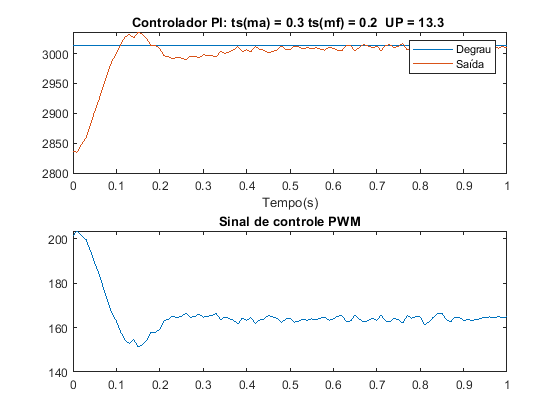

str = sprintf('Controlador PI: ts(ma) = %.1f ts(mf) = %.1f  UP = %.1f ',ts_ma, SettlingTime,UP);
figure
t1=sum(t<2)+1;
subplot(2,1,1);plot(t(t1:end)-2,Y(t1:end,[1,3]));legend('Degrau','Saída');xlabel('Tempo(s)');title(str);
subplot(2,1,2);plot(t(t1:end)-2,Y(t1:end,2));title('Sinal de controle PWM');

2.2 Compare o projeto via LR e via método lambda, considerando a flexibilidade e complexidade de projeto por eles oferecida.

Via LR, o projeto do controlador é mais visual e interativo (pelo matlab). Projetar desta forma te dá uma flexibilidade maior de enxergar os parâmetros que o usuário consegue variar e adicionar, além de ver a resposta. Como há mais parâmetros para visualizar, ele pode ficar complicado caso um sistema tenha mais polos e zeros.

Via Método Lambda, não é tão visualmente melhor de se enxergar, mas como se tem apenas um parâmetro para mexer, que é o lambda, pode ser mais simples de analisar, visto que você só precisa lidar com um parâmetro e ver se as condições são satisfeitas.

## Atividade 3 - Projeto do controlador PID via LR

3.1 Seja C o controlador PI selecionado na atividade 2.1. Adicione ao projeto o zero do ganho derivativo, gere o controlador C6, e veja as melhorias que consegue nos resultados, simulando o controlador no motor. Como escolheu a localização do zero?

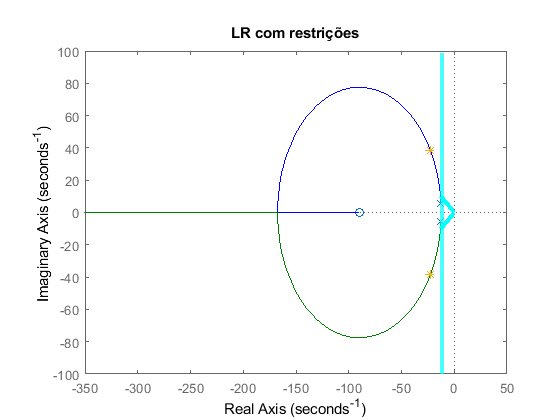

figure;
desenhalr(C6,g2,ts_ma);

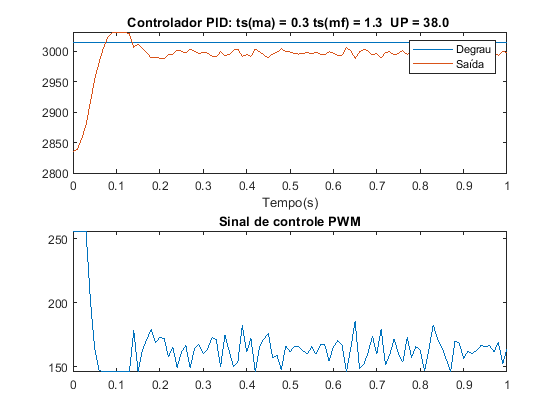

[kp,ki,kd]=piddata(C6); 
[Y,t]=simula_slx(arquivo,Tempo);
[~,UP,SettlingTime] = desempenho(Y(:,[2,3]),t,Ref,2);
str = sprintf('Controlador PID: ts(ma) = %.1f ts(mf) = %.1f  UP = %.1f ',ts_ma, SettlingTime,UP);
figure
t1=sum(t<2)+1;
subplot(2,1,1);plot(t(t1:end)-2,Y(t1:end,[1,3]));legend('Degrau','Saída');xlabel('Tempo(s)');title(str);
subplot(2,1,2);plot(t(t1:end)-2,Y(t1:end,2));title('Sinal de controle PWM');



datetime('now')

ans = datetime
   05-Aug-2021 11:20:58


pwd

ans = 'C:\Users\malaquias\Desktop\UFES\UFES-LCA\Original\Aula8'